
clear
Bounds = [0 500]; N=10; %plot grid resoluti
[x,y]=meshgrid(linspace(Bounds(1),Bounds(2)),linspace(Bounds(1),Bounds(2)));
z=Eggholder(x ,y);
figure
contour(x,y,z,100);
hold on; grid on; axis equal;

err=10^-9;
max_iter=1000;
x=[2; 2];
f = @(X) Eggholder(X(1),X(2)); % the function to be minimized
g = @OptDet2D_df; % the function's gradient
LOG=zeros(max_iter,2);
LOG(1,:)=x';

%% iteration
for curr_iter = 2:max_iter 
	x_prev=x;
	p=-g(x); p=p/norm(p); % step direction
	a=fminsearch(@(a)f(x+a*p),0);
	x=x+a*p; % next point
	LOG(curr_iter,:)=x';
	if norm(x-x_prev)<err 
		curr_iter
		break % solution found 
	end
end

curr_iter = 3

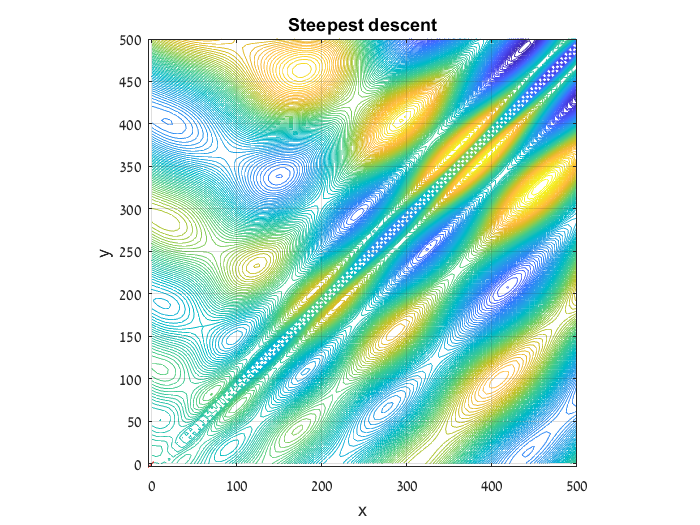

LOG(curr_iter:end,:)=[]; %remove trailing zeros
plot(LOG(:,1),LOG(:,2),'-.r');
xlabel('x'); ylabel('y'); title('Steepest descent');

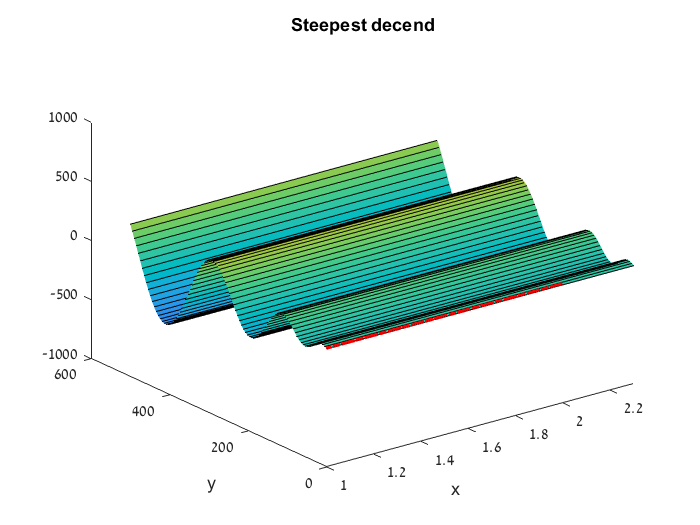



[x,y]=meshgrid(linspace(Bounds(1),Bounds(2)),linspace(Bounds(1),Bounds(2)));
z = Eggholder(x ,y);
Z = Eggholder(LOG(:,1),LOG(:,2));
figure; hold on;
surf(x,y,z)
plot3(LOG(:,1),LOG(:,2),Z,'-.r','linewidth',2);
xlim([1,2.3])
view(3)
xlabel('x'); ylabel('y'); title('Steepest decend');

function y=OptDet2D_df(X)
x=X(1); y=X(2);
y = (Eggholder(x+0.01 ,y+0.01)-Eggholder(x ,y))/0.01;

end